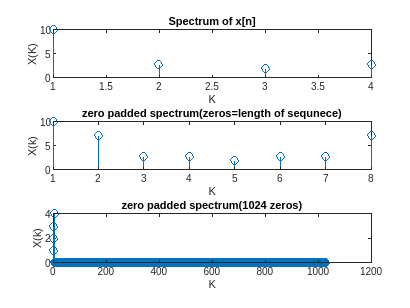

clc;clear;
L=4;
x=[1 2 3 4];
X=abs(fft(x));
x_pd1=[x,zeros(1,L)];
x_pd2=[x,zeros(1,1024)];
X_pd1=fft(x_pd1);
X_pd2=fft(x_pd2);
figure(2);
subplot(3,1,1),stem(abs(X)),xlabel('K'),ylabel('X(K)'),title('Spectrum of x[n]');
subplot(3,1,2),stem(abs(X_pd1)),xlabel('K'),ylabel('X(k)'),title('zero padded spectrum(zeros=length of sequnece)');
subplot(3,1,3),stem(abs(x_pd2)),xlabel('K'),ylabel('X(k)'),title('zero padded spectrum(1024 zeros)');